for a harmonic oscillator


$$\frac{\mathrm{dx}}{\mathrm{dt}}=\mathrm{dp},\frac{\mathrm{dp}}{\mathrm{dt}}=-\mathrm{kx}$$


% 点数
N = 2000;
% x的范围;
x= linspace(-1,1,N);
% x的初始值;
x_0 = -0.5;

% 常数
C = 1;
a = 2e-3;
k = 400;

% 位移和时间步长
dx = 1e-3;
dt = 5*1e-7;

dt*20000

ans = 0.0100

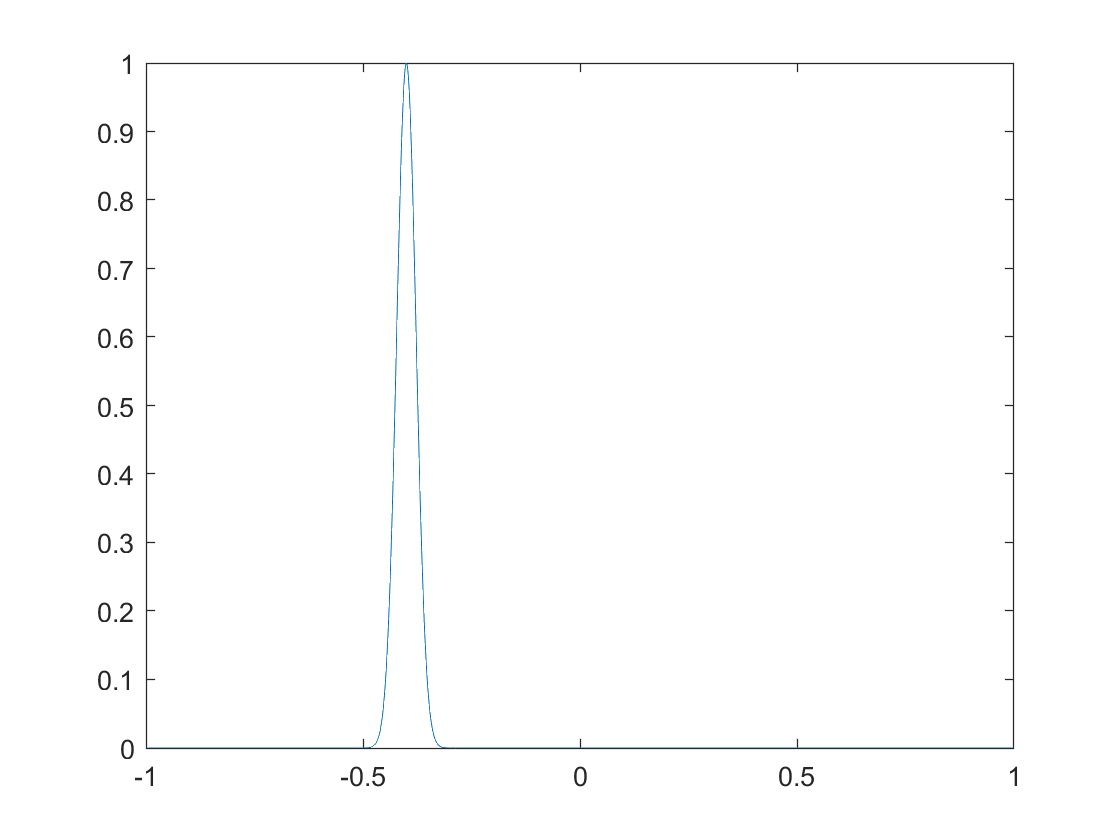

psi0 = C*exp(-(x-x_0).^2/a).*exp(1i*k*x);
plot(x,real(psi).^2+imag(psi).^2)

% 提取虚部和实部
R_0 = real(psi0);
I_0 = imag(psi0);
I_next = zeros(1,N);
R_next = zeros(1,N);


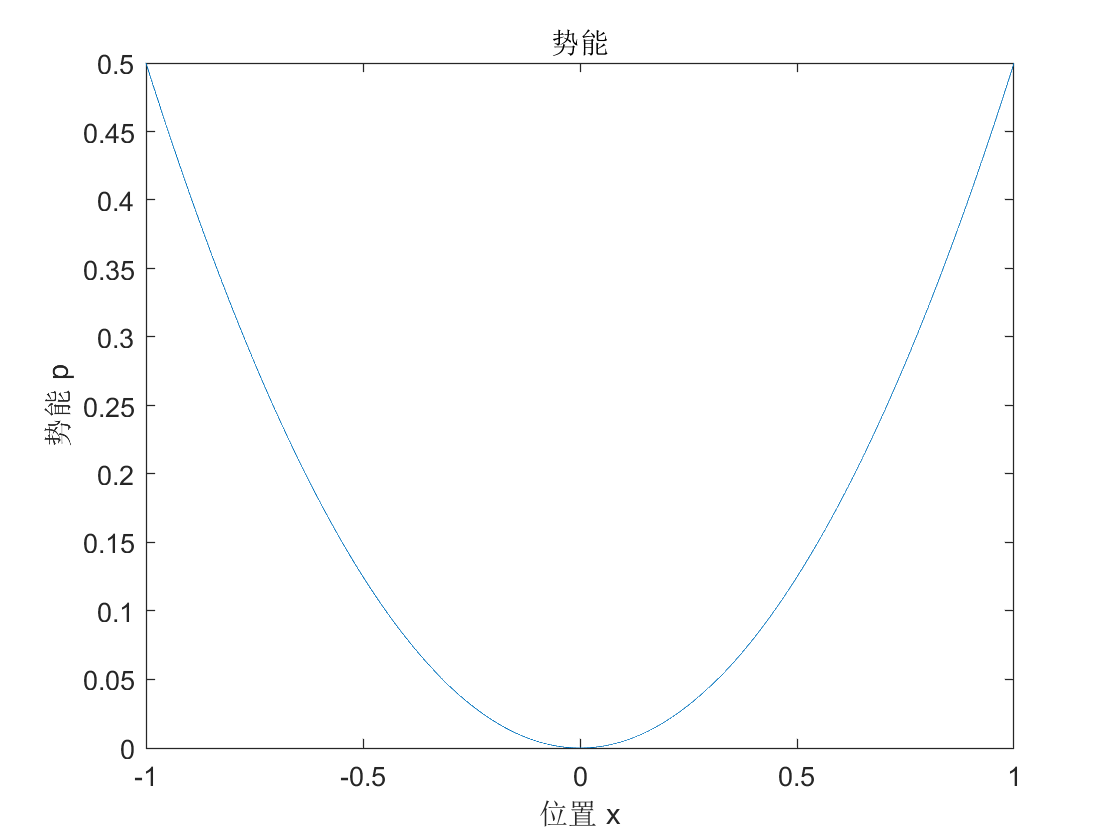

% 创建谐振子势
V=0.5.*x.*x;

% 画出V的图像
plot(x,V)
title('势能');
xlabel('位置 x');
ylabel('势能 p');
pause(2)


% 初始化当前的实部和虚部
I_now = I_0;
R_now = R_0;

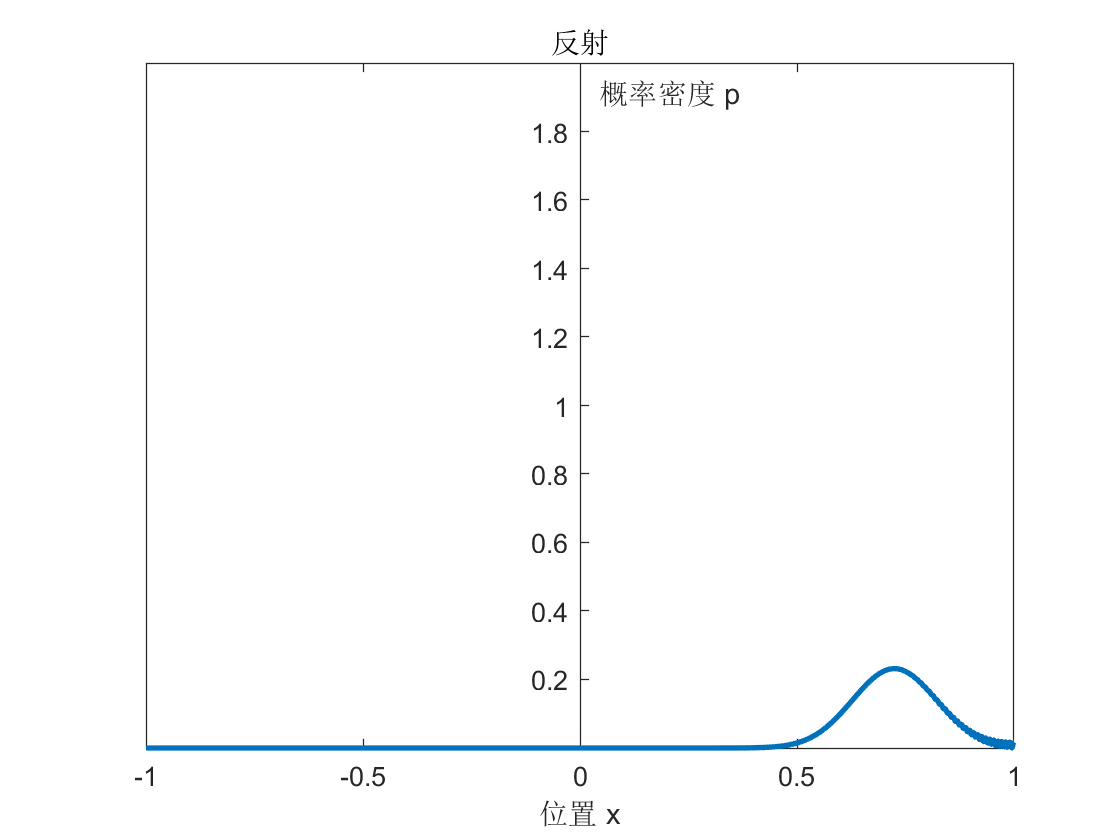


% for n = 2:N-1
%    % t时刻I的值
%    I_next(n) = I_now(n)+dt/(2*dx^2)*(R_now(n+1)-2*R_now(n)+R_now(n-1))-dt*V(n).*R_now(n);
%    % 边界值
%    I_next(1) = I_next(2);
%    I_next(N) = I_next(N-1);
% end

for t = 1:20000

    for n = 2:N-1
        % t时刻R的值
        R_next(n) = R_now(n)-dt/(2*dx^2)*(I_now(n+1)-2*I_now(n)+I_now(n-1))+dt*V(n).*I_now(n);
        % 边界值
        R_next(1) = R_next(2);
        R_next(N) = R_next(N-1);
    end
    R_now = R_next;
    
    for n = 2:N-1
        % t时刻I的值
        I_next(n) = I_now(n)+dt/(2*dx^2)*(R_now(n+1)-2*R_now(n)+R_now(n-1))-dt*V(n).*R_now(n);
        % 边界值 
        I_next(1) = I_next(2);
        I_next(N) = I_next(N-1);
    end
    % 概率密度
    Px = R_now.^2 + I_next.*I_now;
    I_now = I_next;
    
    % 画出t=10的倍数的图像
    if  mod(t, 100) == 0
        plot(x, Px, 'LineWidth',2)
        title('反射');
        axis([-1 1 0 2]);
        xlabel('位置 x');
        ylabel('概率密度 p');
        set(gca,'XAxisLocation','origin','YAxisLocation','origin')
        drawnow;
    end
end